### Clear WorkSpace before running the network

clc;
close all;
clear;

### Prepare network data 

####  load images

parentDir = 'D:\Engineer43269\Mohamad\AE with Wavelet\Results\Data 64 minibatch\Piece wise 64 mini 01lr\Netwrok Data';
dataDir =  'Netwrok Data';
imds = imageDatastore(fullfile(parentDir,dataDir),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

#### Determine the split up


total_split=countEachLabel(imds)

total_split = 4×2 table
    Label     Count
    ______    _____

    D2         621 
    D4         729 
    Load       546 
    NoLoad     683 


num_images=length(imds.Labels)

num_images = 2579

####  Visualize random images

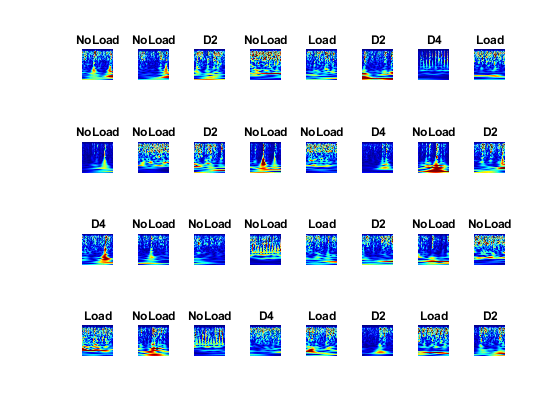

perm=randperm(num_images,32);
figure;
for idx=1:length(perm)
    
    subplot(4,8,idx);
    imshow(imread(imds.Files{perm(idx)}));
    title(sprintf('%s',imds.Labels(perm(idx))))
    
end

### K-fold Validation

Processing 1 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         63  
    D4         72  
    Load       55  
    NoLoad     68  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         558 
    D4         657 
    Load       491 
    NoLoad     615 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       20.31% |       25.97% |       2.8992 |      10.5088 |          0.1000 |
|       1 |          36 |       00:00:39 |       32.81% |       25.97% |       1.3681 |       1.3980 |          0.1000 |
|       2 |          50 |       00:00:52 |       28.12% |              |       1.4030 |              |          0.1000 |
|       2 |          72 |       00:01:10 |       21.88% |       32.17% |       1.5723 |       1.5162 |          0.

Processing 2 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       55  
    NoLoad     68  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       491 
    NoLoad     615 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       20.31% |       23.26% |       2.9077 |      10.9575 |          0.1000 |
|       1 |          36 |       00:00:33 |       26.56% |       22.48% |       1.4973 |       1.4550 |          0.1000 |
|       2 |          50 |       00:00:44 |       23.44% |              |       1.3606 |              |          0.1000 |
|       2 |          72 |       00:01:03 |       21.88% |       23.26% |       1.5903 |       1.4622 |          0.

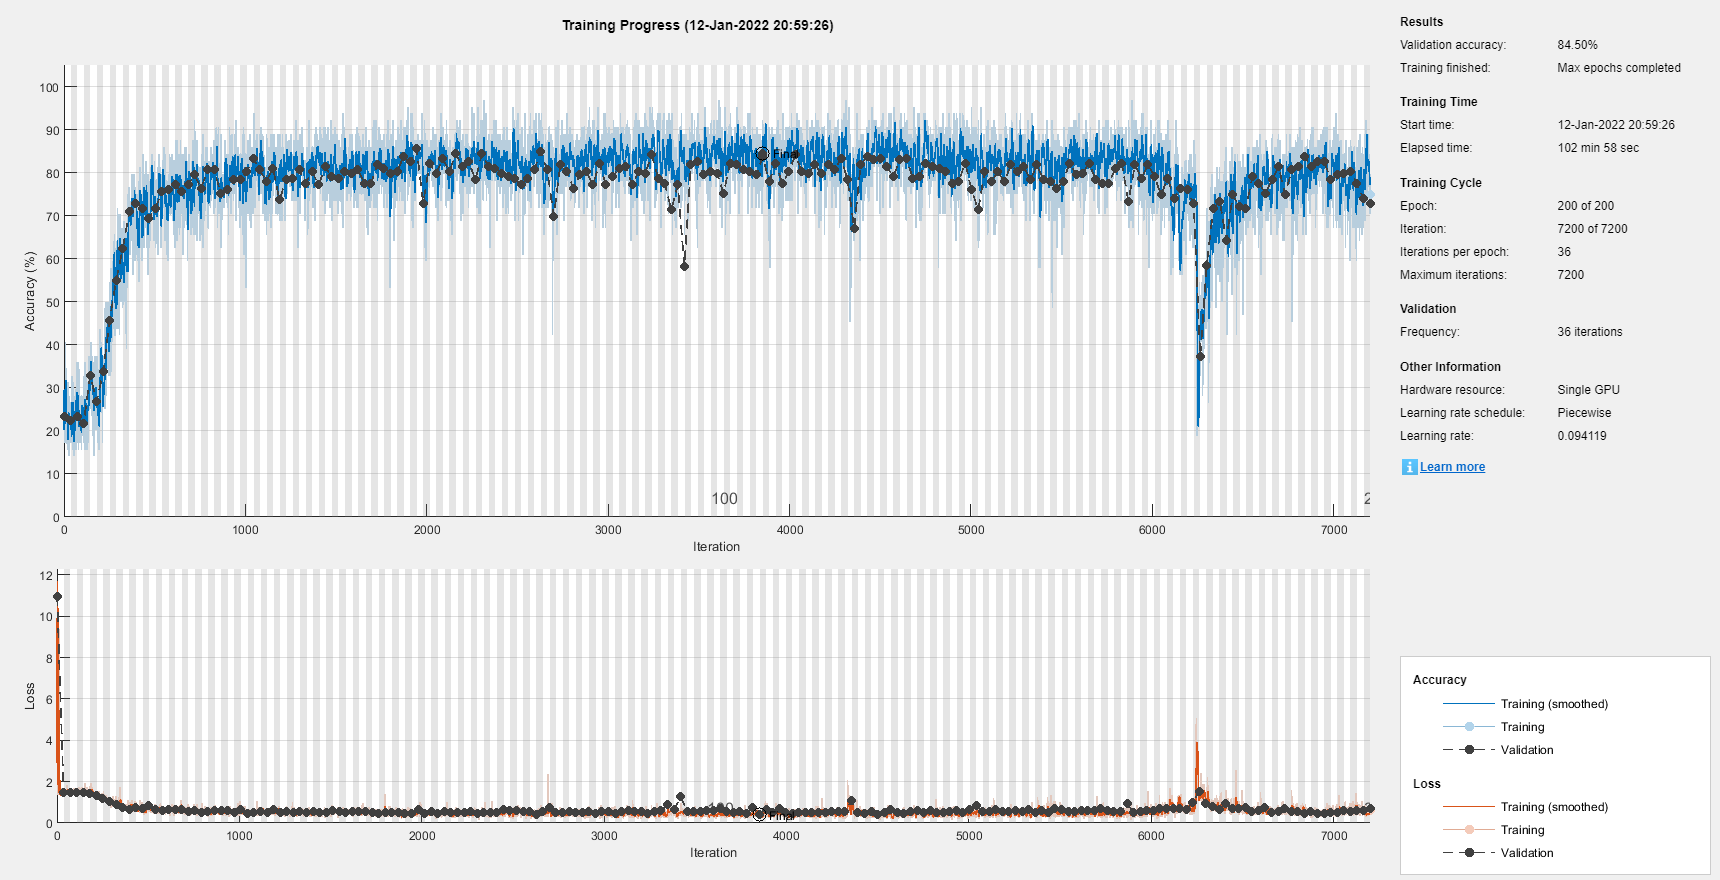

Processing 3 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       55  
    NoLoad     68  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       491 
    NoLoad     615 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       20.31% |       23.64% |       2.8906 |      10.9460 |          0.1000 |
|       1 |          36 |       00:00:34 |       28.12% |       24.03% |       1.4250 |       1.4443 |          0.1000 |
|       2 |          50 |       00:00:46 |       20.31% |              |       1.3781 |              |          0.1000 |
|       2 |          72 |       00:01:05 |       25.00% |       32.56% |       1.6261 |       1.4950 |          0.

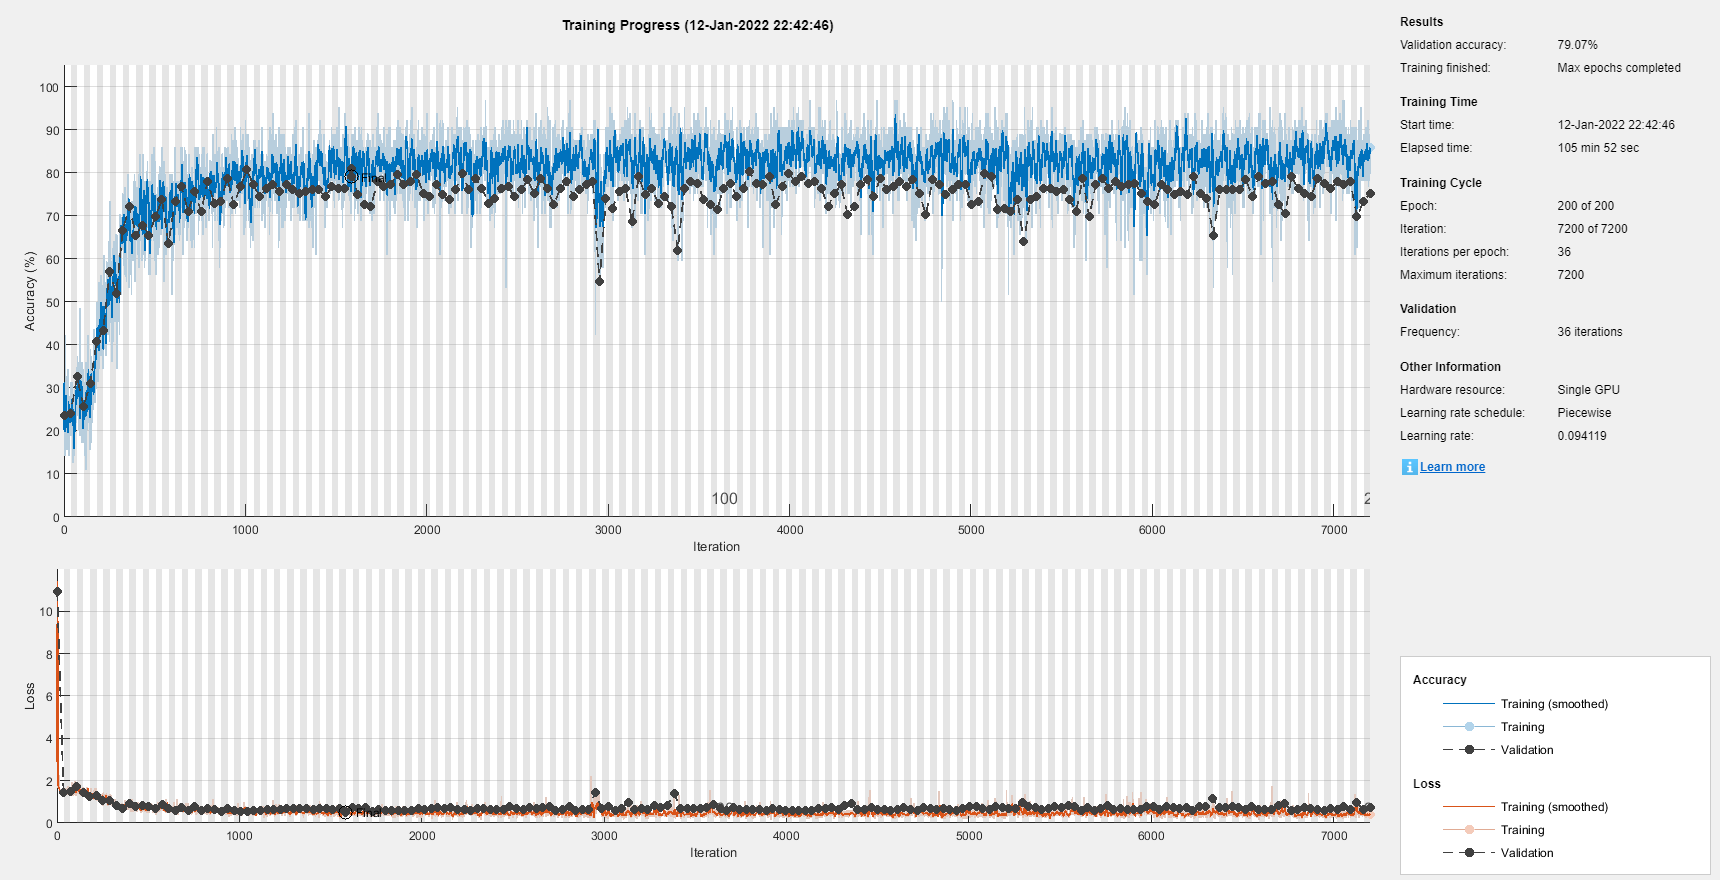

Processing 4 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       55  
    NoLoad     68  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       491 
    NoLoad     615 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       20.31% |       26.36% |       2.9117 |      11.0839 |          0.1000 |
|       1 |          36 |       00:00:35 |       32.81% |       25.97% |       1.3710 |       1.4291 |          0.1000 |
|       2 |          50 |       00:00:47 |       26.56% |              |       1.3207 |              |          0.1000 |
|       2 |          72 |       00:01:08 |       26.56% |       32.17% |       1.5828 |       1.6055 |          0.

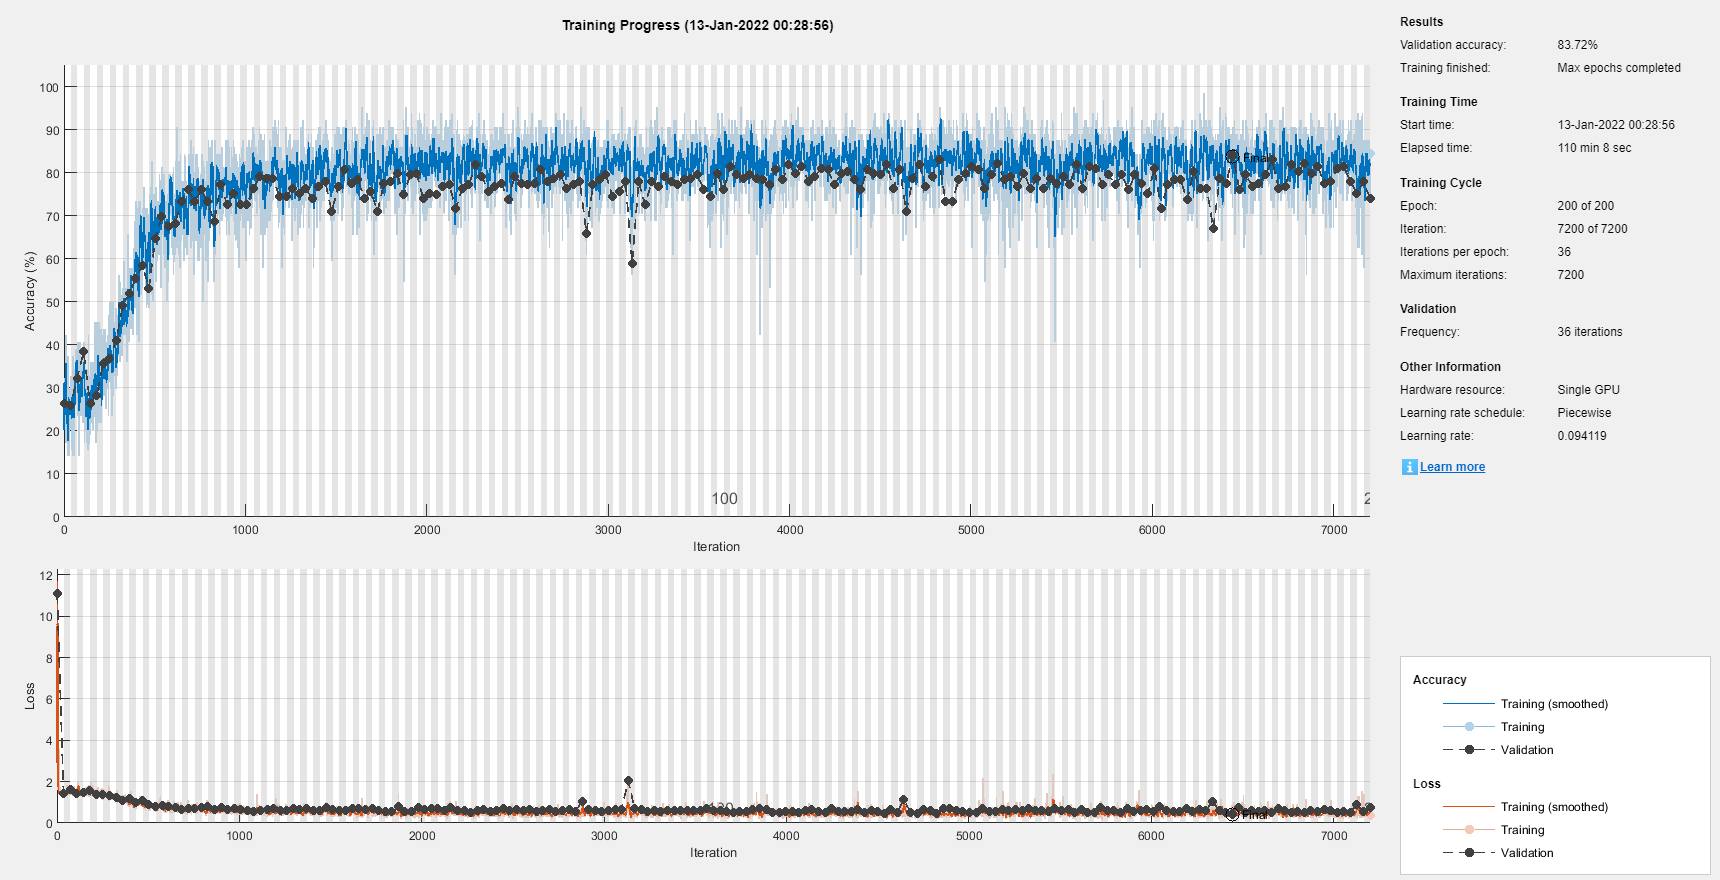

Processing 5 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       55  
    NoLoad     68  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       491 
    NoLoad     615 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       20.31% |       24.03% |       2.8914 |      11.4579 |          0.1000 |
|       1 |          36 |       00:00:36 |       37.50% |       27.13% |       1.4876 |       1.3624 |          0.1000 |
|       2 |          50 |       00:00:49 |       29.69% |              |       1.3620 |              |          0.1000 |
|       2 |          72 |       00:01:10 |       23.44% |       25.97% |       1.3255 |       1.4580 |          0.

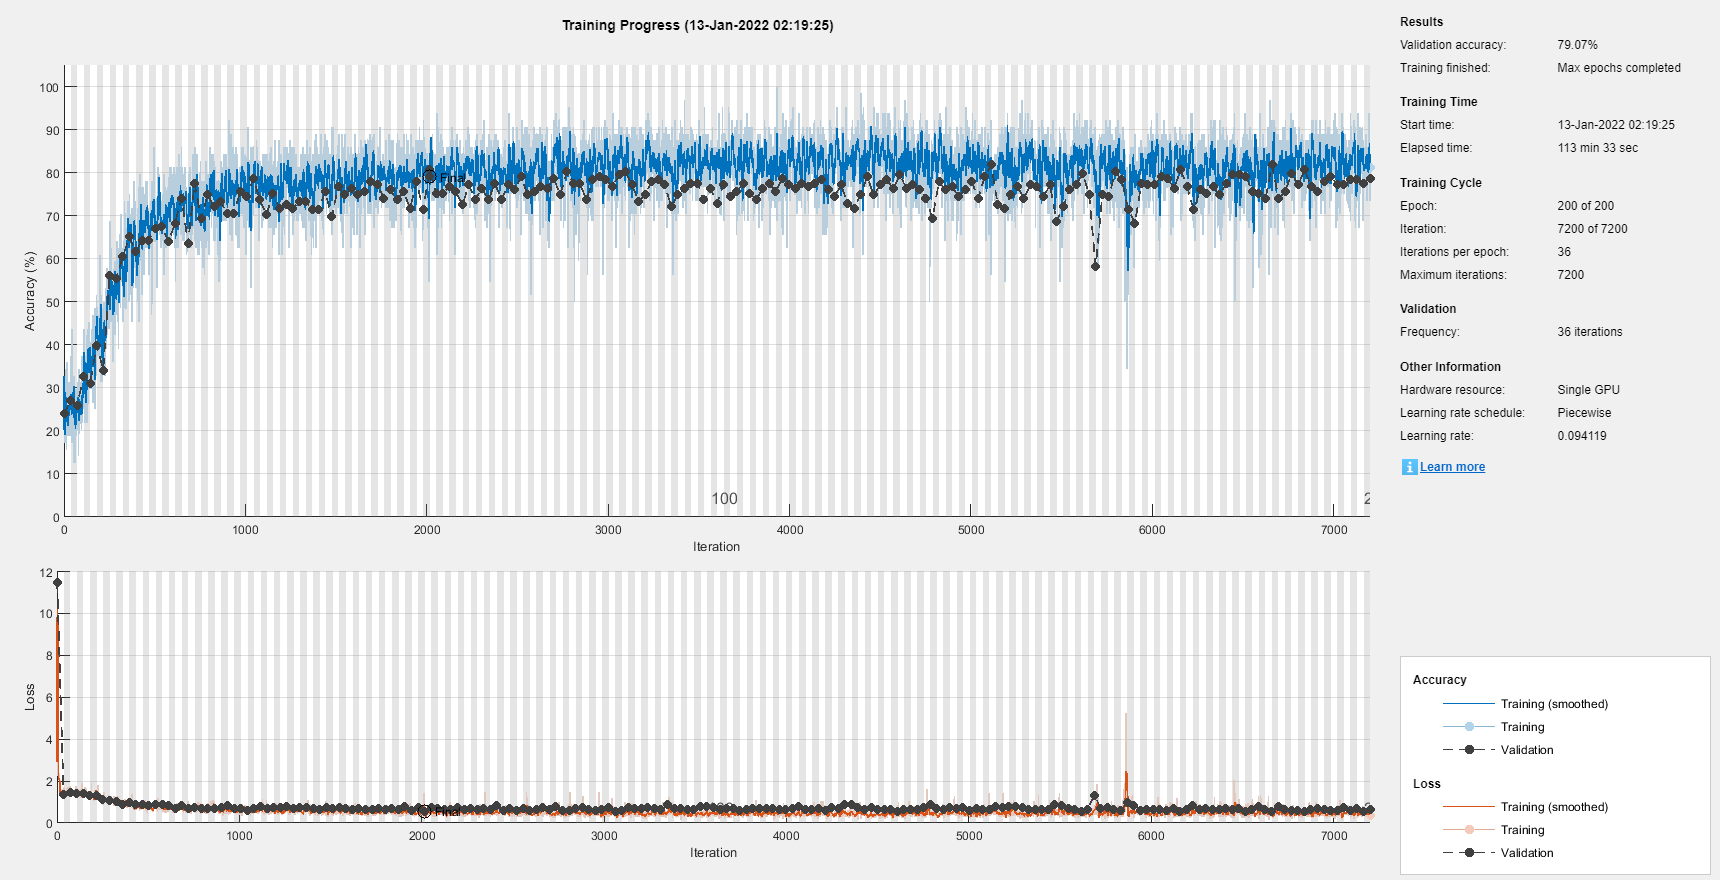

Processing 6 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       55  
    NoLoad     68  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       491 
    NoLoad     615 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       20.31% |       27.52% |       2.8986 |      10.8146 |          0.1000 |
|       1 |          36 |       00:00:37 |       32.81% |       28.68% |       1.5101 |       1.3632 |          0.1000 |
|       2 |          50 |       00:00:51 |       17.19% |              |       1.5415 |              |          0.1000 |
|       2 |          72 |       00:01:12 |       29.69% |       28.68% |       1.4279 |       1.6615 |          0.

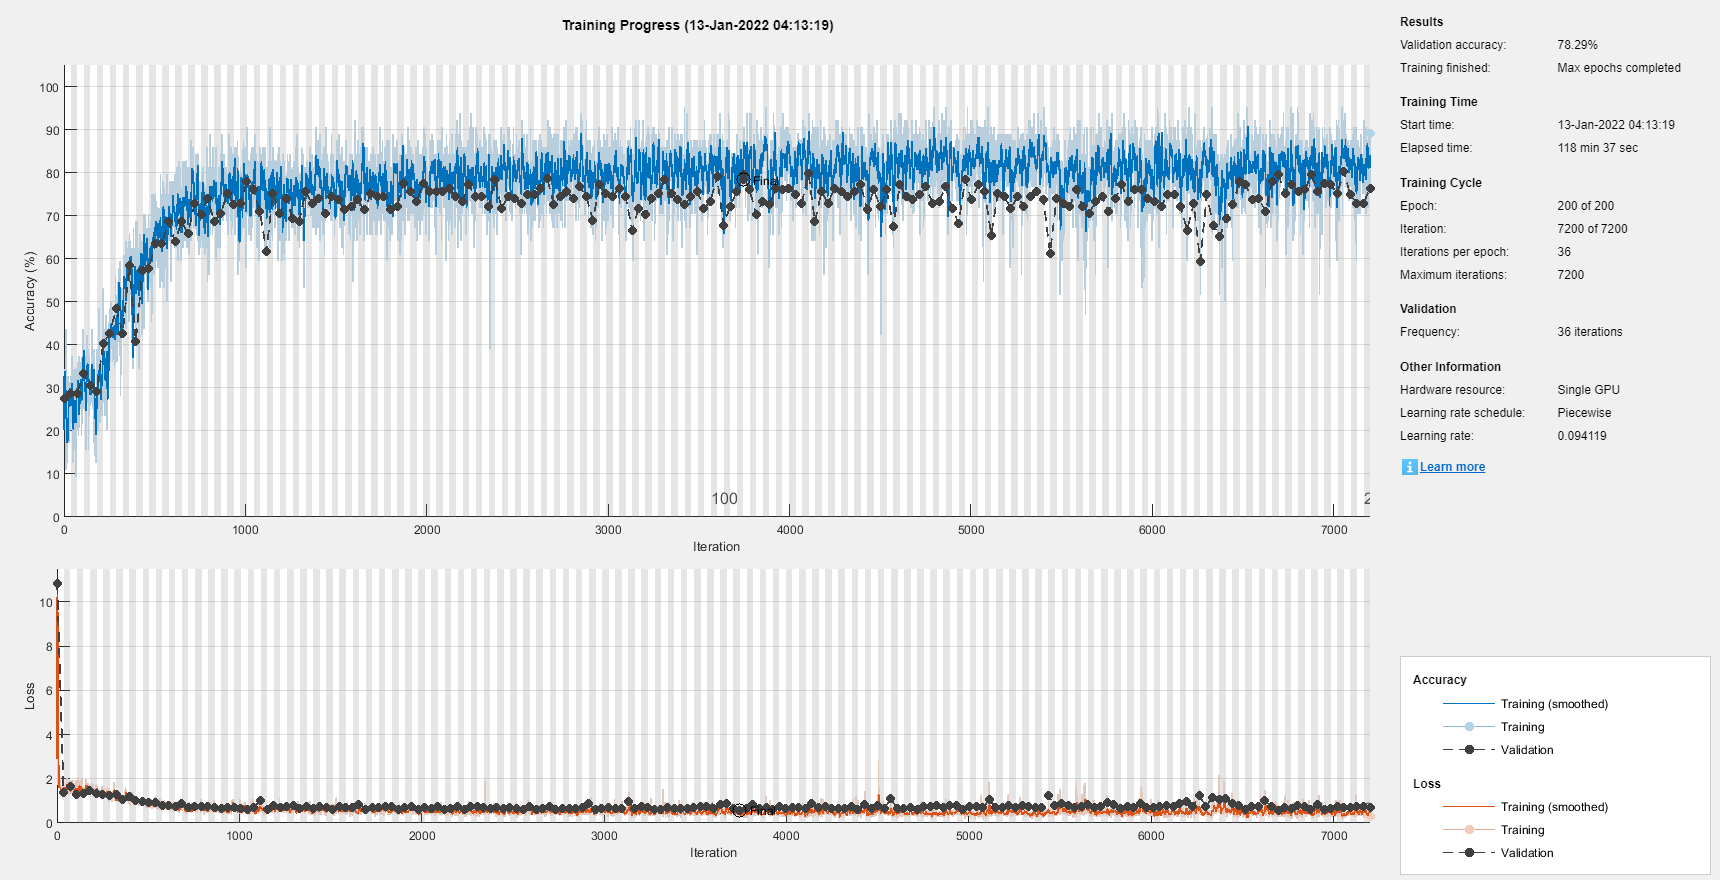

Processing 7 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       54  
    NoLoad     69  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       492 
    NoLoad     614 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       20.31% |       24.42% |       2.8477 |      10.7760 |          0.1000 |
|       1 |          36 |       00:00:39 |       26.56% |       29.46% |       1.3691 |       1.3856 |          0.1000 |
|       2 |          50 |       00:00:53 |       28.12% |              |       1.4171 |              |          0.1000 |
|       2 |          72 |       00:01:16 |       28.12% |       30.62% |       1.3576 |       1.3709 |          0.

Processing 8 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       54  
    NoLoad     69  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       492 
    NoLoad     614 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       20.31% |       28.68% |       2.8411 |       9.5485 |          0.1000 |
|       1 |          36 |       00:00:42 |       32.81% |       26.74% |       1.4660 |       1.4536 |          0.1000 |
|       2 |          50 |       00:00:57 |       28.12% |              |       1.3897 |              |          0.1000 |
|       2 |          72 |       00:01:22 |       21.88% |       27.52% |       1.3793 |       1.5162 |          0.

Processing 9 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       54  
    NoLoad     69  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       492 
    NoLoad     614 


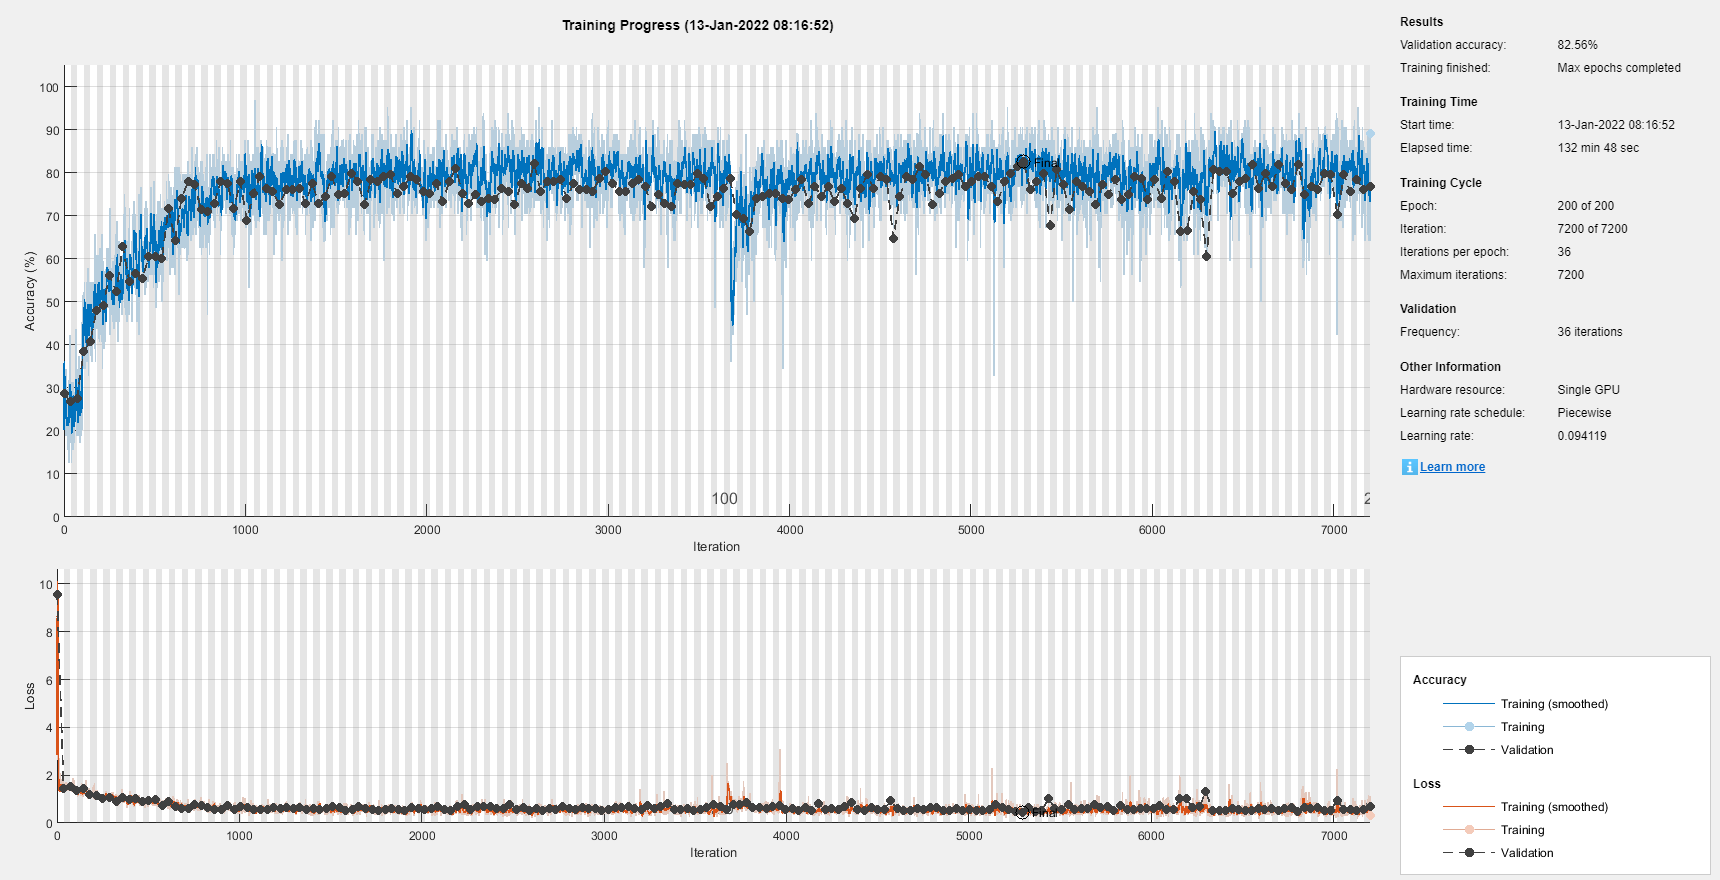

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       20.31% |       25.97% |       2.8546 |       9.6190 |          0.1000 |
|       1 |          36 |       00:00:46 |       29.69% |       28.29% |       1.3436 |       1.3588 |          0.1000 |
|       2 |          50 |       00:01:02 |       29.69% |              |       1.8046 |              |          0.1000 |
|       2 |          72 |       00:01:27 |       43.75% |       32.17% |       1.2668 |       1.4345 |          0.

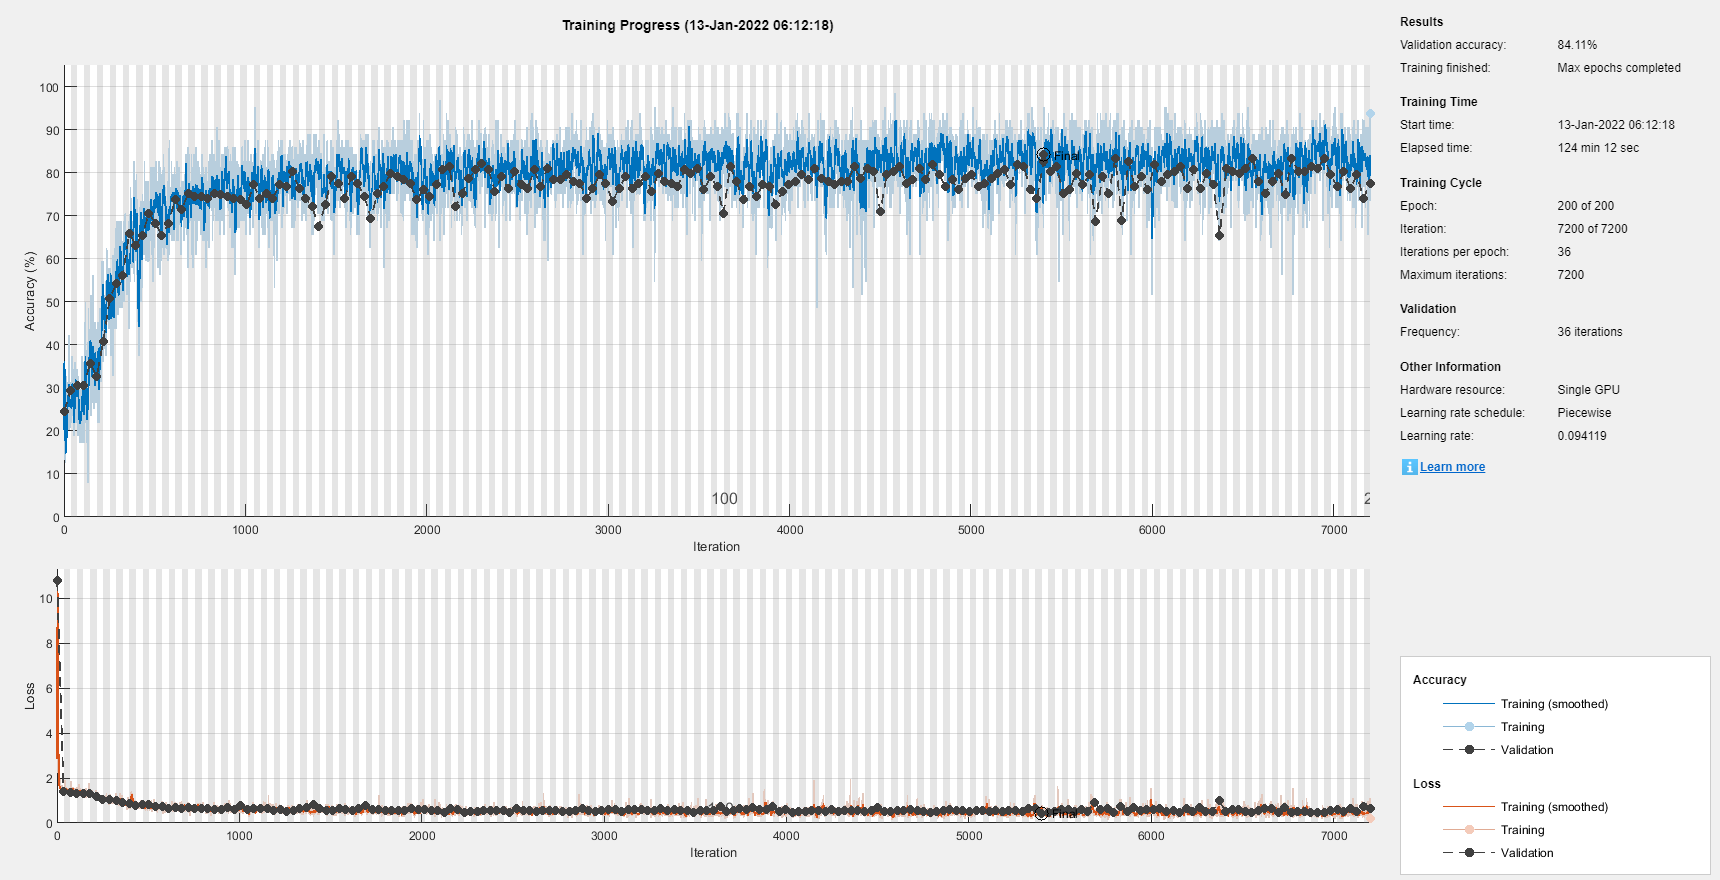

|     194 |        6984 |       02:21:05 |       85.94% |       79.84% |       0.3148 |       0.5257 |          0.0941 |
|     195 |        7000 |       02:21:25 |       87.50% |              |       0.3879 |              |          0.0941 |
|     195 |        7020 |       02:21:50 |       85.94% |       74.42% |       0.4078 |       0.7096 |          0.0941 |
|     196 |        7050 |       02:22:26 |       76.56% |              |       0.5518 |              |          0.0941 |
|     196 |        7056 |       02:22:34 |       75.00% |       77.52% |       0.5766 |       0.5668 |          0.0941 |
|     197 |        7092 |       02:23:18 |       56.25% |       65.12% |       1.3388 |       1.0950 |          0.0941 |
|     198 |        7100 |       02:23:28 |       68.75% |              |       0.8946 |              |          0.0941 |
|     198 |        7128 |       02:24:02 |       65.62% |       69.38% |       1.1817 |       0.9451 |          0.0941 |
|     199 |        7150 |       

Processing 10 among 10 folds 


ans = 4×2 table
    Label     Count
    ______    _____

    D2         62  
    D4         73  
    Load       54  
    NoLoad     68  


ans = 4×2 table
    Label     Count
    ______    _____

    D2         559 
    D4         656 
    Load       492 
    NoLoad     615 


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       20.31% |       26.85% |       2.8315 |       8.8928 |          0.1000 |
|       1 |          36 |       00:00:44 |       37.50% |       29.96% |       1.3627 |       1.4866 |          0.1000 |
|       2 |          50 |       00:01:00 |       28.12% |              |       1.6055 |              |          0.1000 |
|       2 |          72 |       00:01:25 |       21.88% |       28.79% |       1.8229 |       1.3394 |          0.

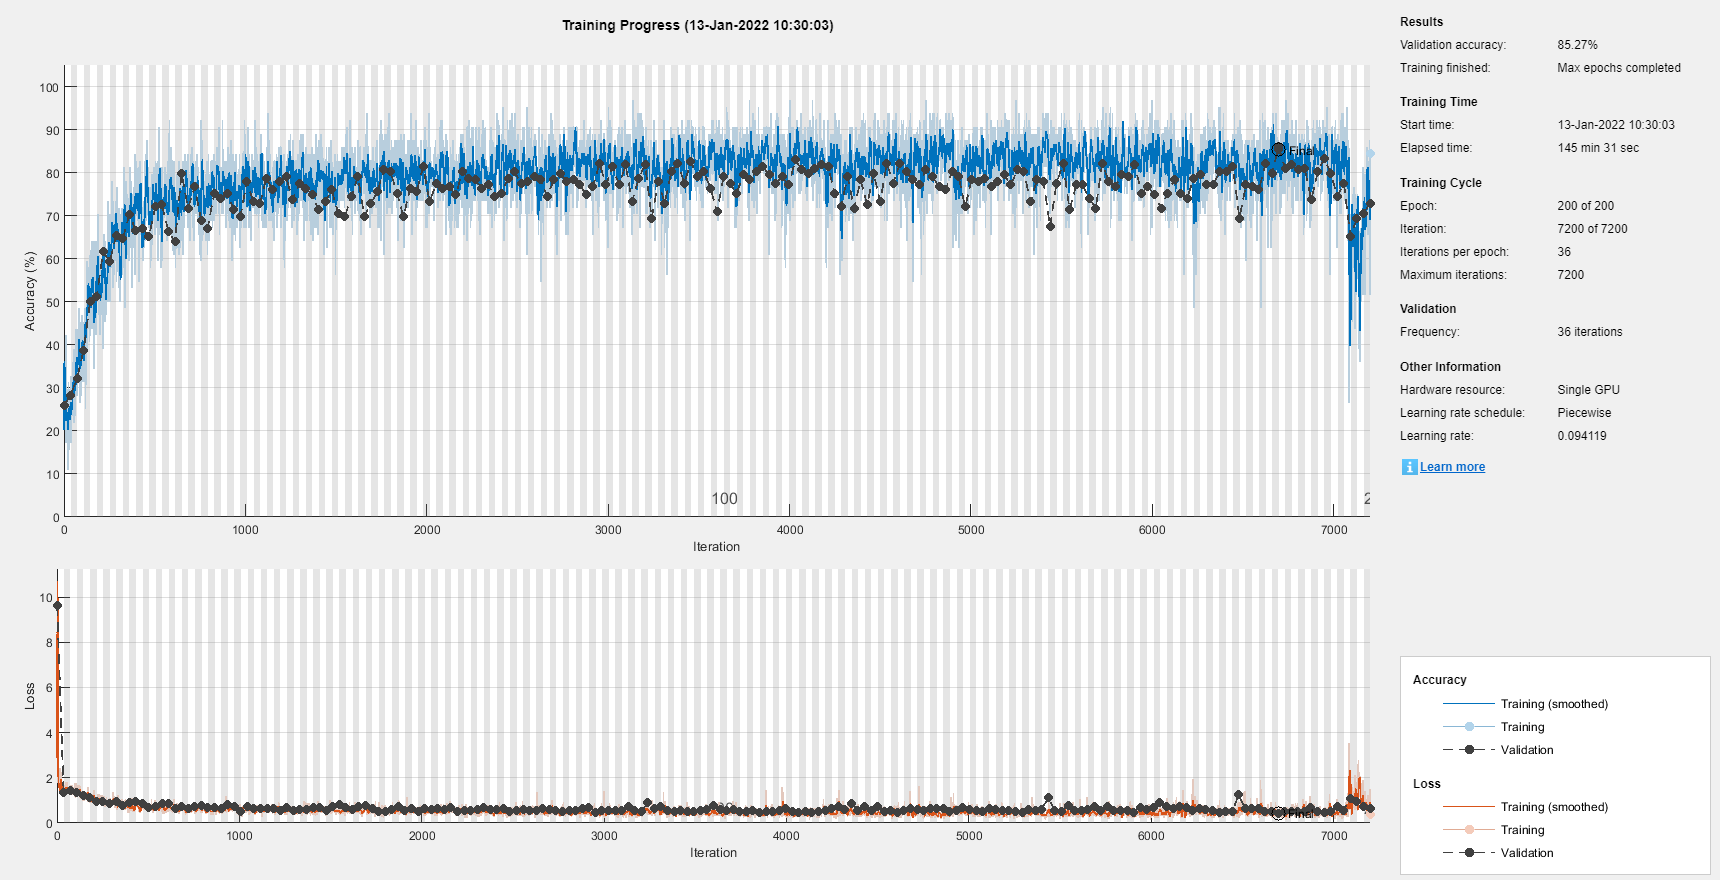

|      37 |        1300 |       00:24:54 |       78.12% |              |       0.4591 |              |          0.1000 |


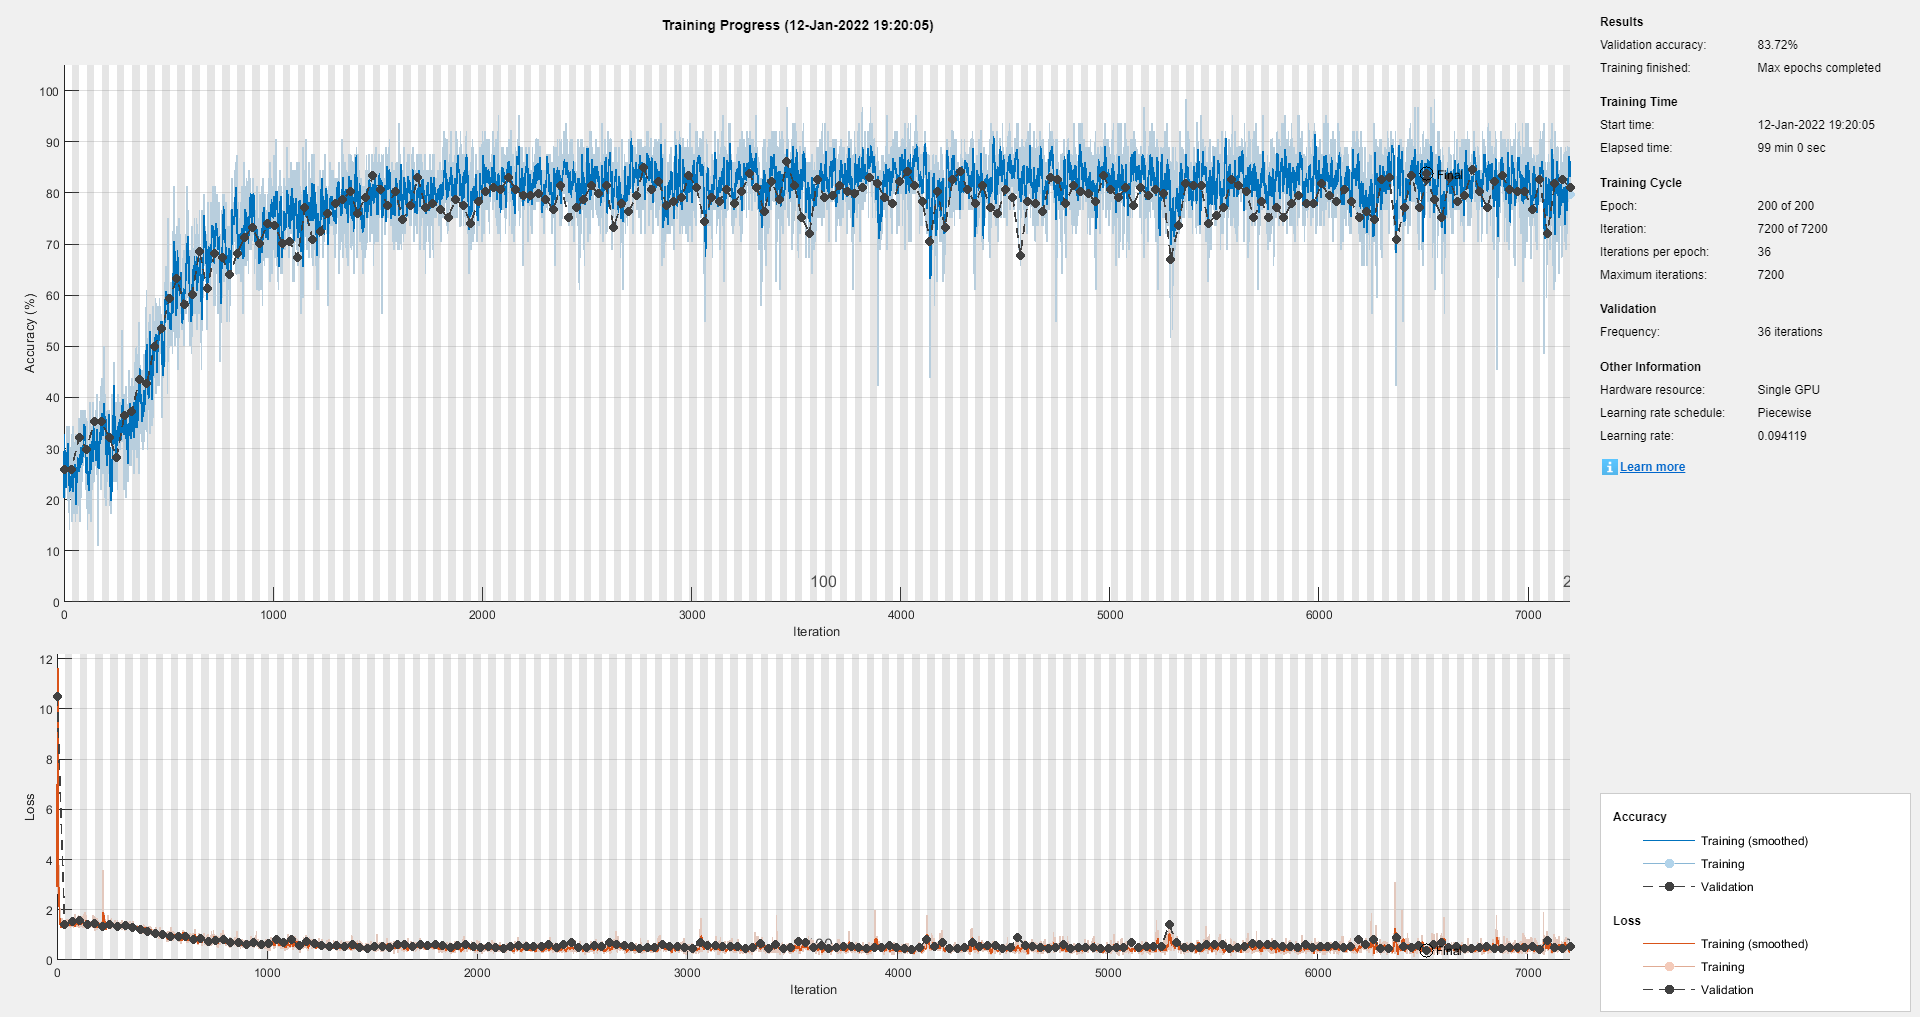

|      37 |        1332 |       00:25:35 |       81.25% |       72.37% |       0.5613 |       0.6466 |          0.1000 |
|      38 |        1350 |       00:25:58 |       71.88% |              |       0.6937 |              |          0.1000 |
|      38 |        1368 |       00:26:21 |       75.00% |       76.26% |       0.7142 |       0.6048 |          0.1000 |
|      39 |        1400 |       00:26:59 |       85.94% |              |       0.5036 |              |          0.1000 |
|      39 |        1404 |       00:27:05 |       70.31% |       74.71% |       0.6048 |       0.6007 |          0.1000 |
|      40 |        1440 |       00:27:49 |       71.88% |       75.88% |       0.6682 |       0.6457 |          0.1000 |
|      41 |        1450 |       00:28:02 |       78.12% |              |       0.5891 |              |          0.1000 |
|      41 |        1476 |       00:28:36 |       82.81% |       80.16% |       0.3443 |       0.5577 |          0.1000 |
|      42 |        1500 |       

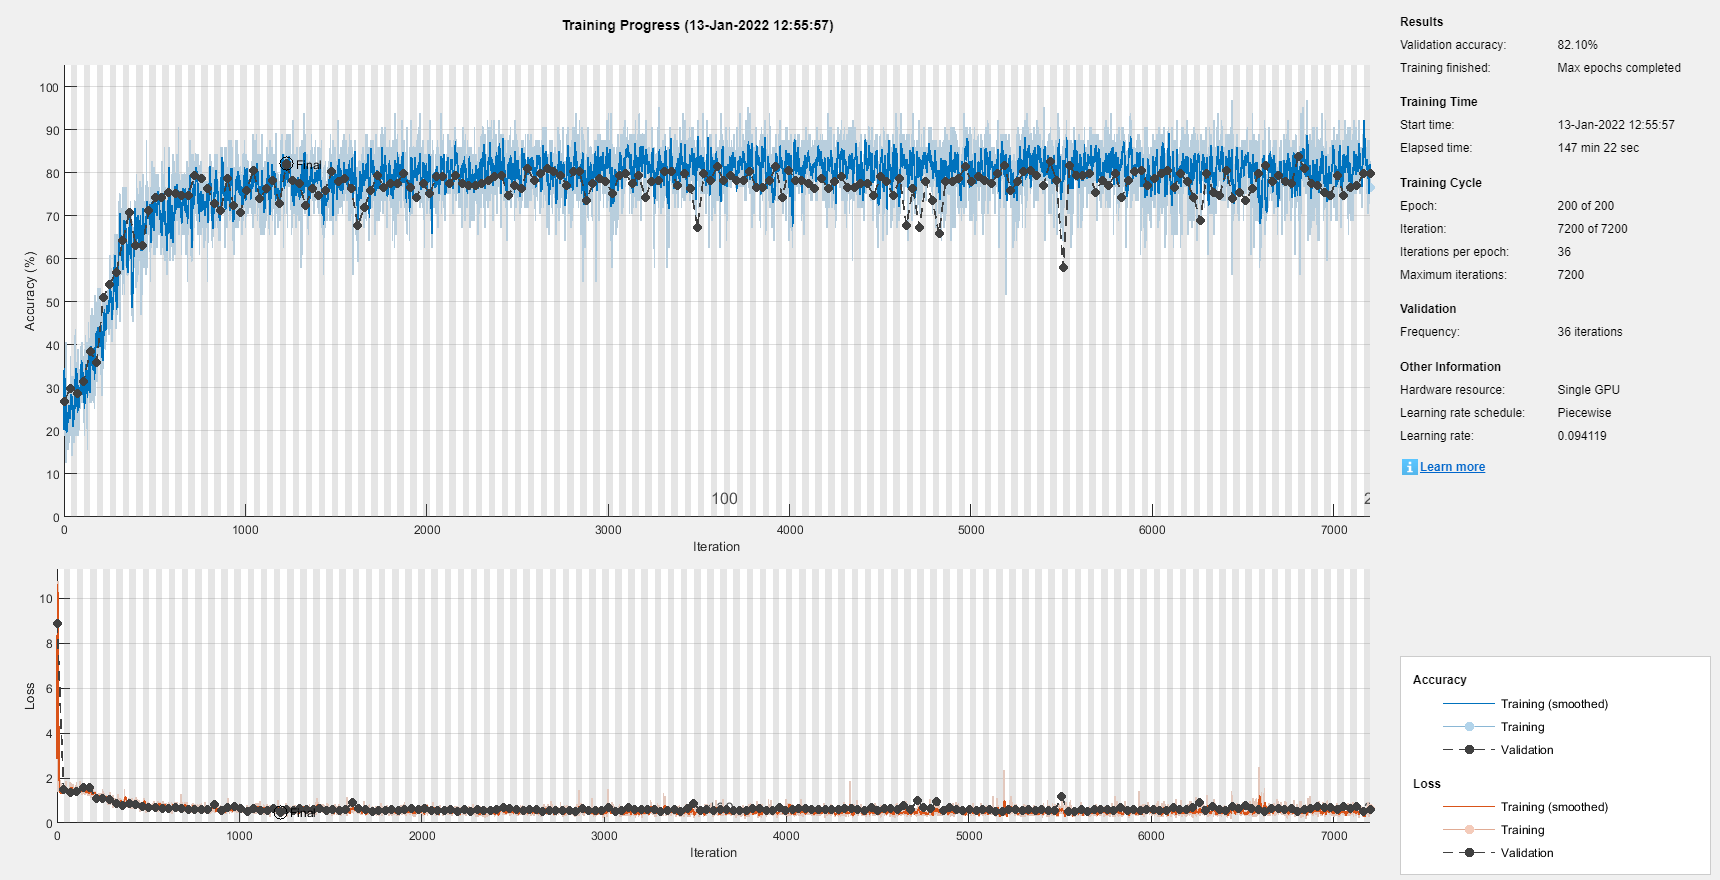

% Number of folds
num_folds=10;
% Loop for each fold
for fold_idx=1:num_folds
    fold_idx=1
    fprintf('Processing %d among %d folds \n',fold_idx,num_folds);
    
   % Test Indices for current fold
    test_idx=fold_idx:num_folds:num_images;
    % Test cases for current fold
    imdsTest = subset(imds,test_idx);
    countEachLabel(imdsTest)
    % Train indices for current fold
    train_idx=setdiff(1:length(imds.Files),test_idx);
    
    % Train cases for current fold
    imdsTrain = subset(imds,train_idx);
    countEachLabel(imdsTrain)
        
    % Number of categories
    numClasses = numel(categories(imdsTrain.Labels));
    
    % ResNet Architecture 
%     net=resnet50;
%     lgraph = layerGraph(net);
%     clear net;
    
    % Replacing the last layers with new layers
%     newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
%     lgraph = replaceLayer(lgraph,'fc1000',newFCLayer);
%     newClassLayer = classificationLayer('Name','new_classoutput');
%     lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

% Load modified network
    res_50
    
    % Training Options, we choose a small mini-batch size due to limited images
    
    ilr = 1e-1;
    miniBatchSize = 64;
    maxEpochs = 200;
    valFreq = floor(numel(imdsTrain.Files)/miniBatchSize);
    opts = trainingOptions('adam',...
        'MiniBatchSize',miniBatchSize,...
        'MaxEpochs',maxEpochs,...
        'LearnRateSchedule','piecewise', ...
        'LearnRateDropFactor',0.98, ...
        'LearnRateDropPeriod',50, ...
        'InitialLearnRate',ilr,...
        'ValidationData',imdsTest,...
        'ValidationFrequency',valFreq,...
        'Verbose',1,...
        'Shuffle','every-epoch', ...
        'ExecutionEnvironment','gpu',...
        'Plots','training-progress', 'OutputNetwork', 'best-validation-loss');
    
       
    rng default
    
      
    % Resizing all training images to [224 224] for ResNet architecture
    auimds = augmentedImageDatastore([224 224],imdsTrain);
    
    % Training
    netTransfer = trainNetwork(auimds,lgraph,opts);
    
    % Resizing all testing images to [224 224] for ResNet architecture   
    augtestimds = augmentedImageDatastore([224 224],imdsTest);
   
    % Testing and their corresponding Labels and Posterior for each Case
    [predicted_labels(test_idx),posterior(test_idx,:)] = classify(netTransfer,augtestimds);
    
    % Save the Independent ResNet Architectures obtained for each Fold
    save(sprintf('ResNet18_%d_among_%d_folds',fold_idx,num_folds),'netTransfer','test_idx','train_idx');
    
    % Clearing unnecessary variables 
    clearvars -except fold_idx num_folds num_images predicted_labels posterior imds netTransfer parentDir dataDir numClasses
    workspacename = ['ws' num2str(fold_idx) '.mat'];
    save(workspacename)
end

## Performance Study


% Actual Labels
actual_labels=imds.Labels;

## Data Cleansing

% Remove undefined data that related to test class from prediction array
TF = isundefined(predicted_labels);
posterior_2= posterior(~TF,:);
test_labels_2 = test_labels(~TF);
actual_labels_2 = actual_labels(~TF);
predicted_labels_2 = predicted_labels(~TF);

### Confusion Matrix

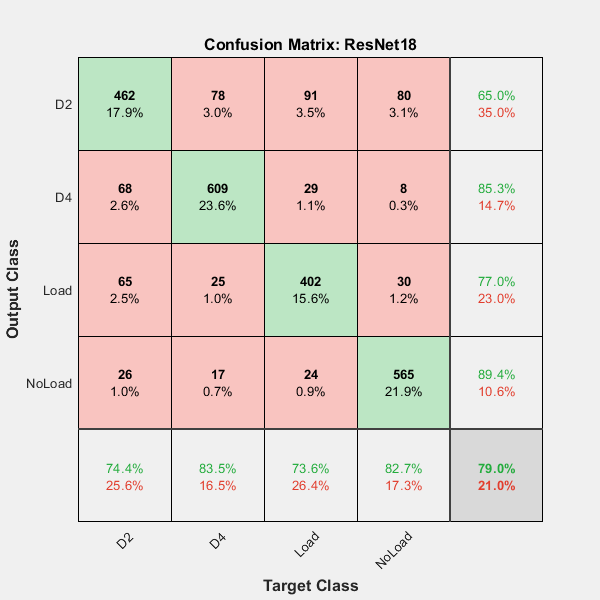

figure;
%plotconfusion(actual_labels,predicted_labels')
confusionchart(actual_labels_2,predicted_labels_2','Normalization','column-normalized');
title('Confusion Matrix: ResNet50');

### Evaluation for all classes

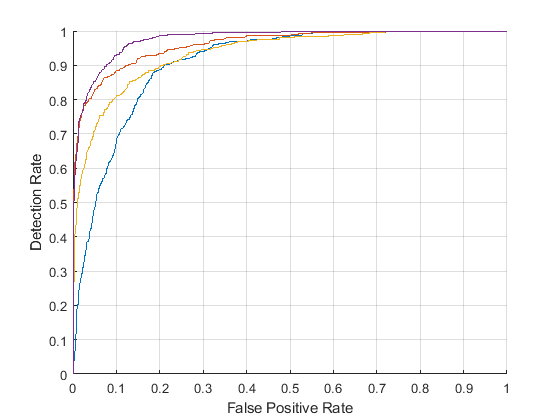

test_labels=double(nominal(imds.Labels));
ClassCats = categories(actual_labels);
% Create tabel for results 
sz = [numClasses 17];
varTypes = ["string","double","double","double","double","double","double","double","double",...
    "double","double","double","double","double","double","double","double"];
varNames = ["ClassName", "AUC","accuracy","sensitivity","specificity","precision","recall",...
    "f_measure","gmean", "Positive", "Negative","True_positive", "True_negative", "False_positive",...
    "False_negative", "True_positive_rate", "True_negative_rate"];
temps = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);



% ROC Curve - For all classes
figure;
hold on
for i = 1: numClasses
    [fp_rate,tp_rate,T,AUC]=perfcurve(test_labels_2,posterior_2(:,i),i);
    plot(fp_rate,tp_rate,"DisplayName",char(ClassCats(i)));
    ACTUAL=actual_labels_2;
    PREDICTED=predicted_labels_2';
    idx = (ACTUAL()==char(ClassCats(i)));
    temps.ClassName(i) = char(ClassCats(i));
    temps.AUC(i) = AUC;
    temps.Positive(i) = length(ACTUAL(idx));
    temps.Negative(i) = length(ACTUAL(~idx));
    N = temps.Positive(i)+temps.Negative(i);
    temps.True_positive(i) = sum(ACTUAL(idx)==PREDICTED(idx));
    temps.True_negative(i) = sum(ACTUAL(~idx)==PREDICTED(~idx));
    temps.False_positive(i) = temps.Negative(i)-temps.True_negative(i);
    temps.False_negative(i) = temps.Positive(i)-temps.True_positive(i);
    temps.True_positive_rate(i) = temps.True_positive(i)/temps.Positive(i);
    temps.True_negative_rate(i) = temps.True_negative(i)/temps.Negative(i);
    temps.accuracy(i) = (temps.True_positive(i)+temps.True_negative(i))/N;
    temps.sensitivity(i) = temps.True_positive_rate(i);
    temps.specificity(i) = temps.True_negative_rate(i);
    temps.precision(i) = temps.True_positive(i)/(temps.True_positive(i)+temps.False_positive(i));
    temps.recall(i) = temps.sensitivity(i);
    temps.f_measure(i) = 2*(( temps.precision(i)*temps.recall(i))/(temps.precision(i) + temps.recall(i)));
    temps.gmean(i) = sqrt(temps.True_positive_rate(i)*temps.True_negative_rate(i));
    
    
end
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');


parentDir = 'D:\Engineer43269\Mohamad\AE with Wavelet\Results\Data 64 minibatch\Piece wise 64 mini 01lr\Netwrok Data';
dataDir =  'Netwrok Data';
imds = imageDatastore(fullfile(parentDir,dataDir),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

 imdsTest = subset(imds,test_idx);
 imdsTrain = subset(imds,train_idx);
 clear posterior predicted_labels




# Generate Results for validation and training data 

## Process Validation data 

 % Create data store for validation data
 augtestimds = augmentedImageDatastore([224 224],imdsTest);
   
 % Testing and their corresponding Labels and Posterior for each Case
 [predicted_labels(test_idx),posterior(test_idx,:)] = classify(netTransfer,augtestimds);
 
 % Actual Labels
actual_labels=imds.Labels;

## Data Cleansing

% Remove undefined data that related to training class from prediction array
test_labels=double(nominal(imds.Labels));
ClassCats = categories(actual_labels);
TF = isundefined(predicted_labels);
posterior_2= posterior(~TF,:);
test_labels_2 = test_labels(~TF);
actual_labels_2 = actual_labels(~TF);
predicted_labels_2 = predicted_labels(~TF);

### Confusion Matrix

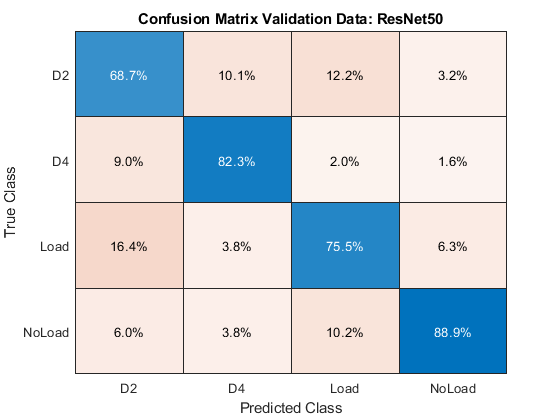

h = figure;
%plotconfusion(actual_labels,predicted_labels')
confusionchart(actual_labels_2,predicted_labels_2','Normalization','column-normalized');
title('Confusion Matrix Validation Data: ResNet50');
set(h,'windowstyle', 'normal')

savefig(['Confusion Matrix Validation Data Fold num_' num2str(fold_idx) '.fig'] )


### Evaluation for all classes

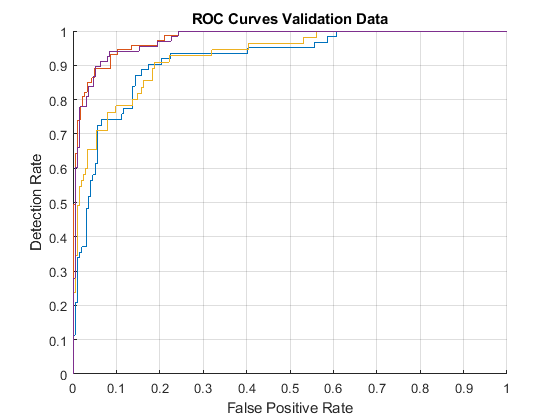

% Create tabel for results 
sz = [numClasses 17];
varTypes = ["string","double","double","double","double","double","double","double","double",...
    "double","double","double","double","double","double","double","double"];
varNames = ["ClassName", "AUC","accuracy","sensitivity","specificity","precision","recall",...
    "f_measure","gmean", "Positive", "Negative","True_positive", "True_negative", "False_positive",...
    "False_negative", "True_positive_rate", "True_negative_rate"];
temps = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);



% ROC Curve - For all classes
h= figure;
hold on
for i = 1: numClasses
    [fp_rate,tp_rate,T,AUC]=perfcurve(test_labels_2,posterior_2(:,i),i);
    plot(fp_rate,tp_rate,"DisplayName",char(ClassCats(i)));
    ACTUAL=actual_labels_2;
    PREDICTED=predicted_labels_2';
    idx = (ACTUAL()==char(ClassCats(i)));
    temps.ClassName(i) = char(ClassCats(i));
    temps.AUC(i) = AUC;
    temps.Positive(i) = length(ACTUAL(idx));
    temps.Negative(i) = length(ACTUAL(~idx));
    N = temps.Positive(i)+temps.Negative(i);
    temps.True_positive(i) = sum(ACTUAL(idx)==PREDICTED(idx));
    temps.True_negative(i) = sum(ACTUAL(~idx)==PREDICTED(~idx));
    temps.False_positive(i) = temps.Negative(i)-temps.True_negative(i);
    temps.False_negative(i) = temps.Positive(i)-temps.True_positive(i);
    temps.True_positive_rate(i) = temps.True_positive(i)/temps.Positive(i);
    temps.True_negative_rate(i) = temps.True_negative(i)/temps.Negative(i);
    temps.accuracy(i) = (temps.True_positive(i)+temps.True_negative(i))/N;
    temps.sensitivity(i) = temps.True_positive_rate(i);
    temps.specificity(i) = temps.True_negative_rate(i);
    temps.precision(i) = temps.True_positive(i)/(temps.True_positive(i)+temps.False_positive(i));
    temps.recall(i) = temps.sensitivity(i);
    temps.f_measure(i) = 2*(( temps.precision(i)*temps.recall(i))/(temps.precision(i) + temps.recall(i)));
    temps.gmean(i) = sqrt(temps.True_positive_rate(i)*temps.True_negative_rate(i));
    
    
end
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');
title('ROC Curves Validation Data');
savefig(['ROC Curves Validation Data Fold num_' num2str(fold_idx) '.fig'] )

validation_results = temps;

## Process All data together

 % Create data store for validation data
 augtestimds = augmentedImageDatastore([224 224],imdsTrain);
   
 % Testing and their corresponding Labels and Posterior for each Case
 [predicted_labels(train_idx),posterior(train_idx,:)] = classify(netTransfer,augtestimds);
 
 % Actual Labels
actual_labels=imds.Labels;

## Data Cleansing

% Remove undefined data that related to training class from prediction array
test_labels=double(nominal(imds.Labels));
ClassCats = categories(actual_labels);
TF = isundefined(predicted_labels);
posterior_2= posterior(~TF,:);
test_labels_2 = test_labels(~TF);
actual_labels_2 = actual_labels(~TF);
predicted_labels_2 = predicted_labels(~TF);

### Confusion Matrix

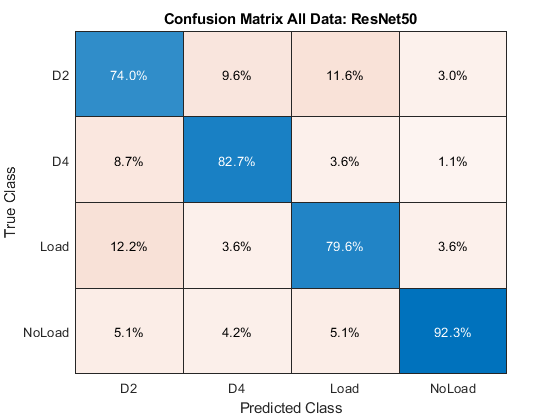

figure;
%plotconfusion(actual_labels,predicted_labels')
confusionchart(actual_labels_2,predicted_labels_2','Normalization','column-normalized');
title('Confusion Matrix All Data: ResNet50');

savefig(['Confusion Matrix All Data Fold num_' num2str(fold_idx) '.fig'] )


### Evaluation for all classes

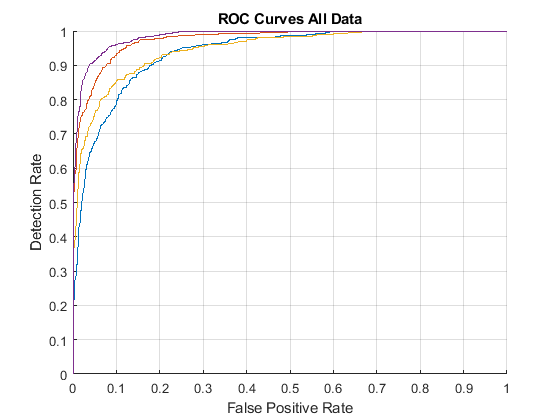

% Create tabel for results 
sz = [numClasses 17];
varTypes = ["string","double","double","double","double","double","double","double","double",...
    "double","double","double","double","double","double","double","double"];
varNames = ["ClassName", "AUC","accuracy","sensitivity","specificity","precision","recall",...
    "f_measure","gmean", "Positive", "Negative","True_positive", "True_negative", "False_positive",...
    "False_negative", "True_positive_rate", "True_negative_rate"];
temps = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);



% ROC Curve - For all classes
figure;
hold on
for i = 1: numClasses
    [fp_rate,tp_rate,T,AUC]=perfcurve(test_labels_2,posterior_2(:,i),i);
    plot(fp_rate,tp_rate,"DisplayName",char(ClassCats(i)));
    ACTUAL=actual_labels_2;
    PREDICTED=predicted_labels_2';
    idx = (ACTUAL()==char(ClassCats(i)));
    temps.ClassName(i) = char(ClassCats(i));
    temps.AUC(i) = AUC;
    temps.Positive(i) = length(ACTUAL(idx));
    temps.Negative(i) = length(ACTUAL(~idx));
    N = temps.Positive(i)+temps.Negative(i);
    temps.True_positive(i) = sum(ACTUAL(idx)==PREDICTED(idx));
    temps.True_negative(i) = sum(ACTUAL(~idx)==PREDICTED(~idx));
    temps.False_positive(i) = temps.Negative(i)-temps.True_negative(i);
    temps.False_negative(i) = temps.Positive(i)-temps.True_positive(i);
    temps.True_positive_rate(i) = temps.True_positive(i)/temps.Positive(i);
    temps.True_negative_rate(i) = temps.True_negative(i)/temps.Negative(i);
    temps.accuracy(i) = (temps.True_positive(i)+temps.True_negative(i))/N;
    temps.sensitivity(i) = temps.True_positive_rate(i);
    temps.specificity(i) = temps.True_negative_rate(i);
    temps.precision(i) = temps.True_positive(i)/(temps.True_positive(i)+temps.False_positive(i));
    temps.recall(i) = temps.sensitivity(i);
    temps.f_measure(i) = 2*(( temps.precision(i)*temps.recall(i))/(temps.precision(i) + temps.recall(i)));
    temps.gmean(i) = sqrt(temps.True_positive_rate(i)*temps.True_negative_rate(i));
    
    
end
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');
title('ROC Curves All Data');
savefig(['ROC Curves All Data Fold num_' num2str(fold_idx) '.fig'] )

AllData_results = temps;

workspacename = ['ws' num2str(fold_idx) '.mat'];
save(workspacename)